## Digital Communications TTT4130 - Matlab Lab Sessions

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments. The live script and the project report must be completed and delivered to BlackBoard**.**

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

### `Project 1`

This first lab session covers the basics of *digital communications. *The students will get an understanding of the *essential *building blocks of generic digital communication systems. In particular, the project is based on the simulation of an equivalent complex baseband representation of a passband system. 

### `Digital Communications System Schematic`

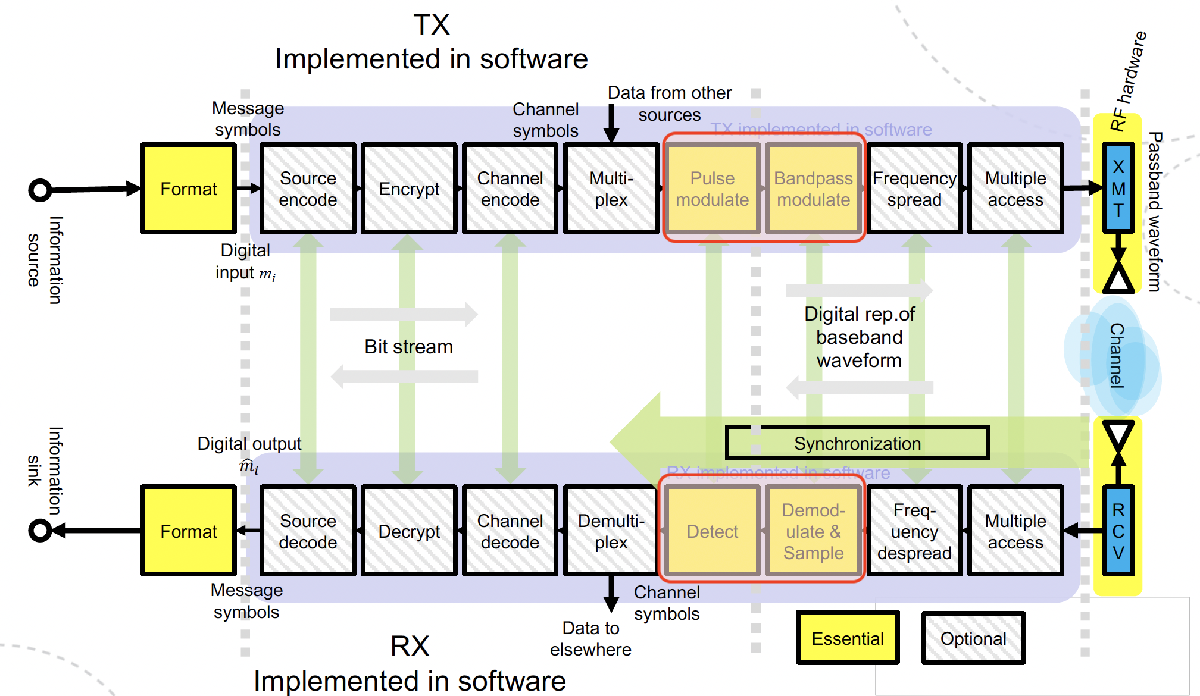

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

`Course Content`

- Principles of digital communication channels

- Digital modulation schemes

- Nyquist pulse shaping 

- Matched filtering

- Additive-White-Gaussian Noise Channels

- BER vs SNR

`Bonus`

- Frame Synchronisation 

**How to use: **

**You can configure parameters of the simulated equivalent baseband digital communication system here in the livescript. Some of these parameters can be changed during simulation runtime from the **`SIMULINK `**dashboard . Running the simulation will also open other windows with plots displaying important communication system statistics.  **

#### `System Configuration`

% Symbol Rate 
symRate = 100;         % 1/s



SNR = Simulink.Parameter(0.1)       % Signal to Noise ratio, specifically Energy per bit to Noise Power density ratio (Eb/No)

SNR =   Parameter with properties:

          Value: 0.1000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


Select modulation scheme

modScheme = "QPSK (Student)"

modScheme = "QPSK (Student)"




% For M-ary QAM specify modulation order 
% NB! Make sure modOrder matches modScheme

modOrder = 4

modOrder = 4

Specify Transmit Filter Parameters

alpha =0.2  % Nyquist Filter Roll-Off Factor

alpha = 0.2000



filterLenSymbols = 10;            % Filter Length in Symbols


samplesPerSymbol = 8;             % Filter Upsampling Factor


`Task 0: Simulink Baseband Communication System`

Arrange and connect the blocks in the enclosed `Simulink `file (*CommSysSimulink.slx*) to achieve a functioning complex equivalent baseband communication simulation.

`Task 1: QPSK/BPSK Modulation`

Implement a function that perfoms digital QPSK/BPSK modulation on a frame of binary input data.

The following mapping rules apply for BPSK:


$$\begin{array}{l}
0\to 1\\
1\to -1
\end{array}$$


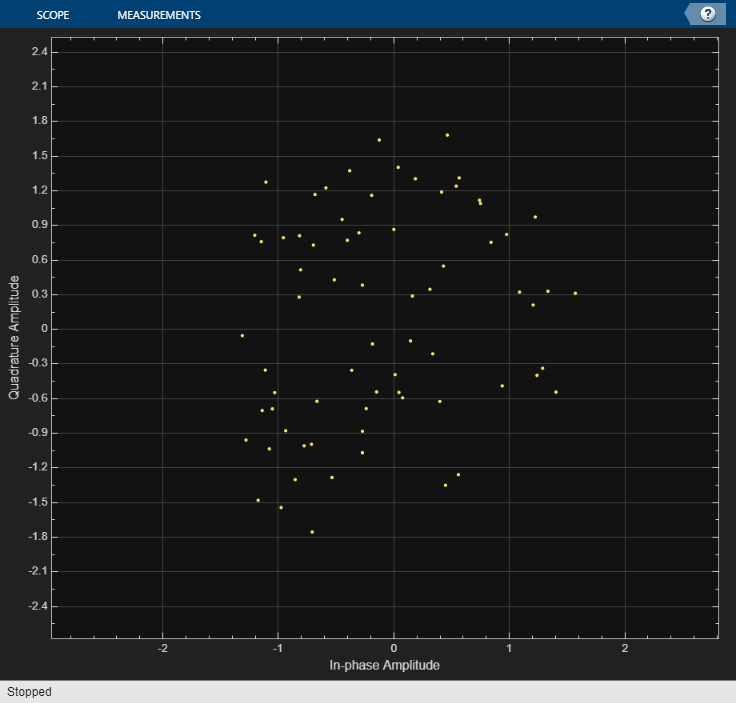

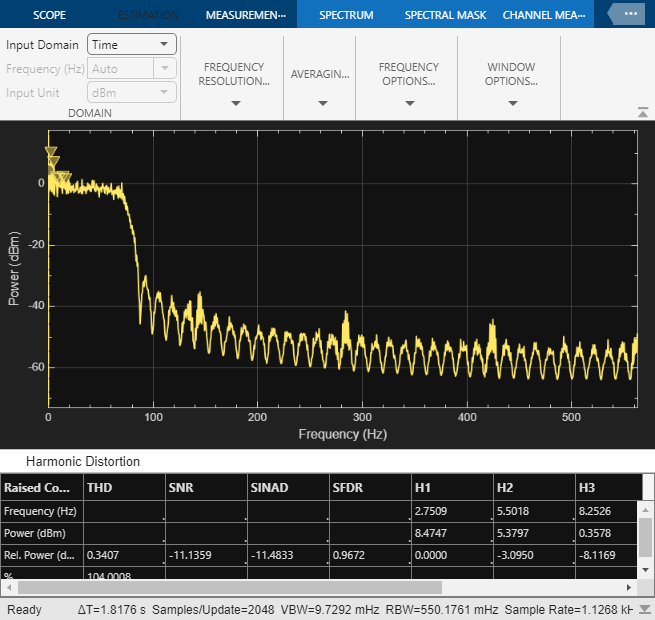

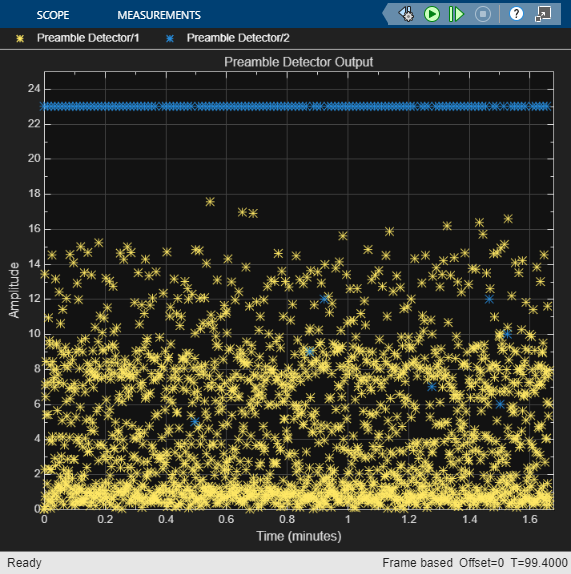

out =   Simulink.SimulationOutput:

                SNRvBER: [1x2x141 double] 
      barkerCodeBipolar: [1833x1 double] 
             corrResult: [1x1 timeseries] 
                  fsIdx: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
          processedBits: [1x1 timeseries] 
                   tout: [142x1 double] 
                txFrame: [14100x1 double] 
                  txMsg: [20022x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


function symOut = BPSKmod(binIn)
%  'binIn' is a binary stream (e.g., 0100011...)
    symOut = 1 - 2 * binIn;
end

Now implement QPSK modulation according to the following specifications:

- **Gray coding with [0,1,3,2] (MSB first) starting in the first quadrant of the complex plane and proceeding in mathematical positive direction**

- **Modulated symbols must have a magnitude of 1 (signal energy) **

- **Phase offset is pi/4**

*01  00*

*11  10*

*odd = 0 -> positive imaginary*

*even = 0 -> positive real*

*symOut = I + jQ*

SNR =   Parameter with properties:

          Value: 0
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 0.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 1
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 1.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 2
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 2.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 3
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 3.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 4
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 4.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 5
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 5.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 6
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 6.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 7
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 7.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 8
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 8.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 9
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 9.5000
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


SNR =   Parameter with properties:

          Value: 10
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


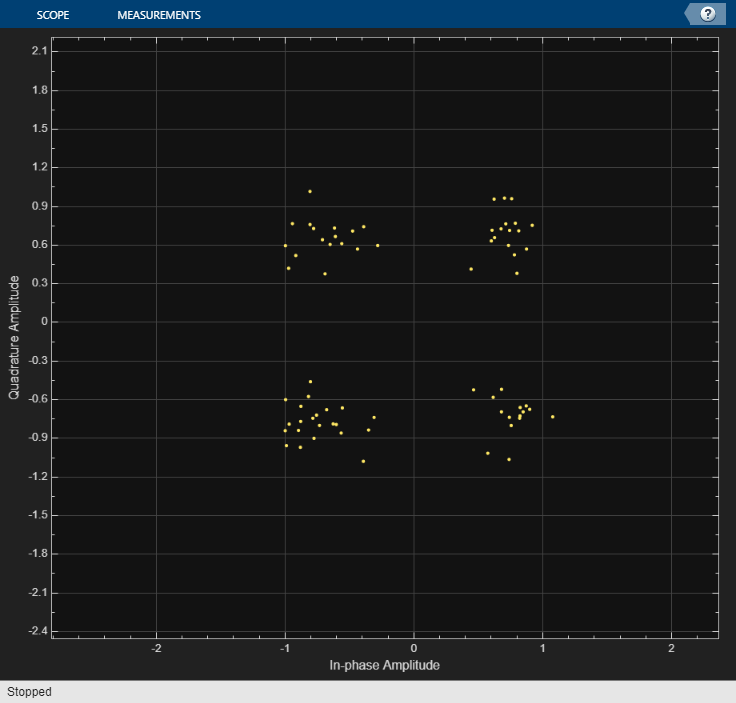

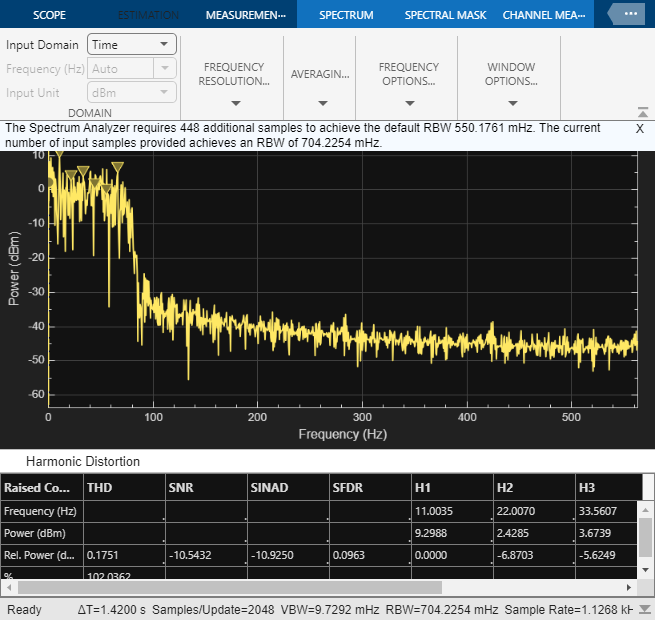

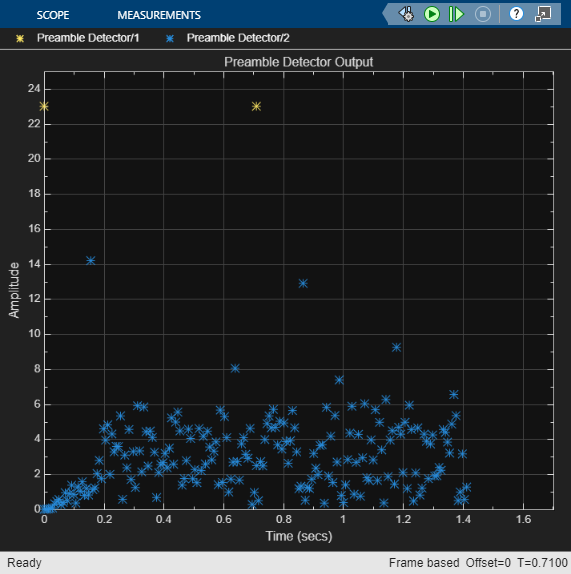

function symOut = QPSKmod(binIn)  % TEMPLATE SOLUTION
    %  'binIn' is a binary stream (e.g., 0100011...) with
    %  len(binIn)%log2(modOrder) = 0
    
    % Array of all odd-indexed values. (e.g., 0 0 0 1...)
    odd = binIn(1 : 2 : end);
    % Array of all even-indexed values. (e.g., 1 0 1 ...)
    even = binIn(2 : 2 : end);
    
    % In case binIn has an odd-length. 
    % (This will not haven, given len(binIn)%log2(modOrder) = 0;
    length = floor(len(binIn)/2);


    % Output
    symOut = (1/sqrt(2))*( (-1).^(even(1:length))  + (-1).^(odd(1:length))*j);

end


Test your BPSK/QPSK modulation implementation by choosing the option `BPSK (Student)/QPSK (Student) `in *modScheme *- SelectionBox

Why is the modulated data complex? Explain. 

*QPSK utilizes phase to modulate (and demodulate) signals. Specifically, sine and cosine waves are orthogonal. Thus, the output signal is the result of a sumation of a sine and cosine wave, of positive or negative amplitude. The resulting wave will be of the same frequency, amplitude 1, and phase equal to a multiple of 45°. The value of the phase will solely depend on the amplitudes (positive or negative), of the inpute waves. In the demodulator, you can determine the phase difference between the sines and cosines used to construct the wave. Then, by knowing the phase difference, you can deduce the aplitudes assigned to your original sine and cosine ways. Finally, you can decode the original bitstream. This process is possible given the fact that sine and cosine are an orthogonal base.*

`RUN THE DIGITAL BASEBAND COMMUNICATION SYSTEM SIMULATION `

`NOTE: ``You can also open the simulink model and run it directly.`

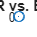

% Simulation Time
simTime = 100;    % Change to 'inf' for indefinite runtime


% Run simulation (simulation output is stored in simout structure)
out = sim("CommSysSimulink.slx",'StopTime',string(simTime),'SimulationMode', 'normal')


`Task 2: Pulse-shaping filter and matched filtering`

Plot the nyquist RRC pulse shape (rcTxFilt) for different values of the roll-off factor. How does the roll-off factor affect the spectral properties of the signal?

*a = 0*

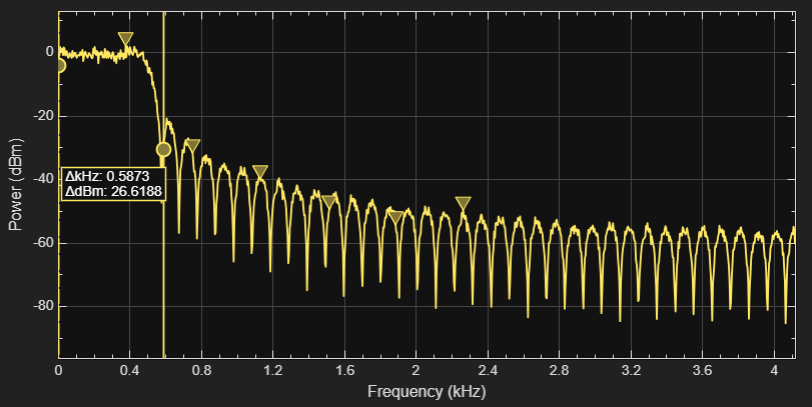

*a=0.2*

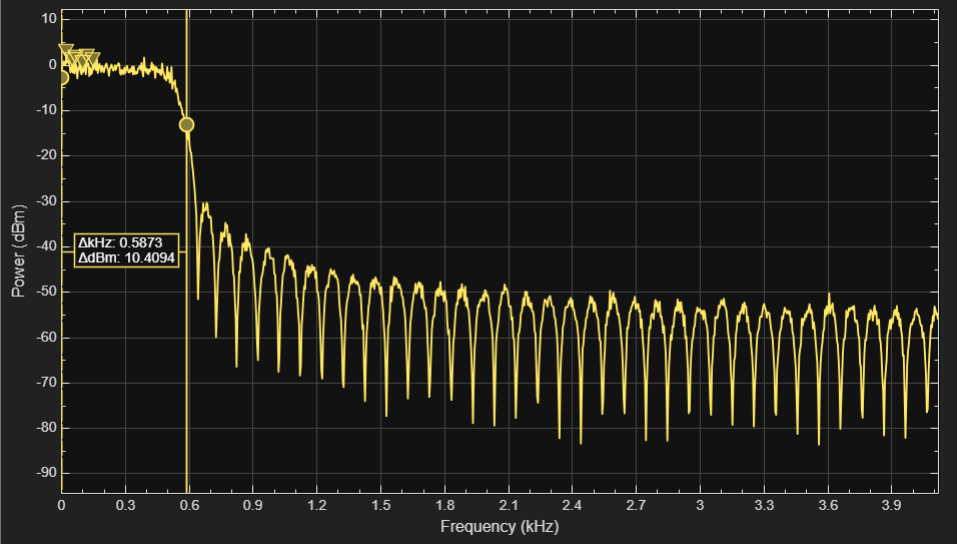

*a = 0.5*

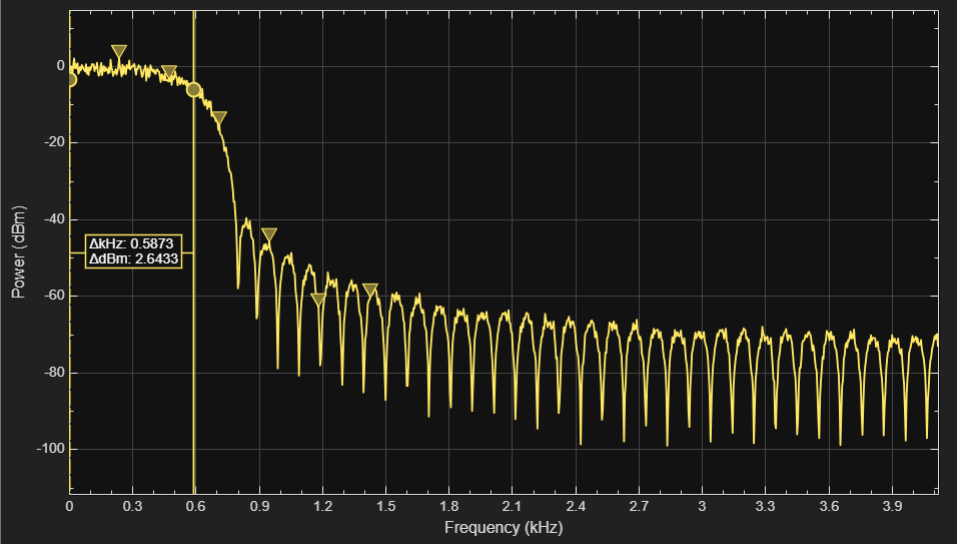

*a = 1*

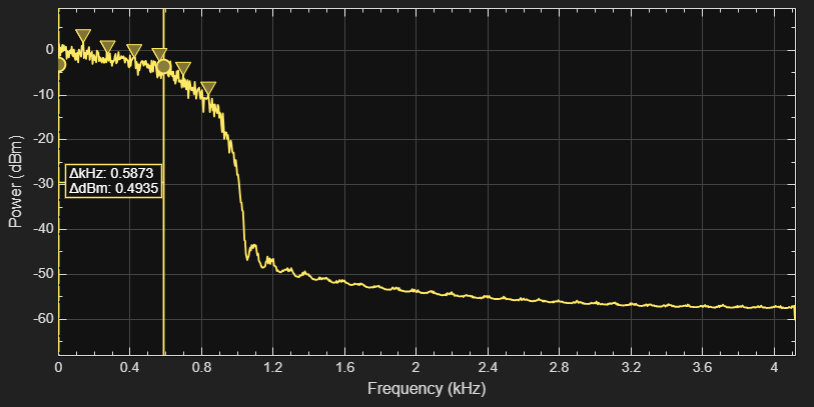

`Task 3: Baseband Bandwidth and Symbol Rate`

Change the symbol rate setting in the live script and observe how the baseband bandwidth of the signal changes.

*symbol rate = 100*

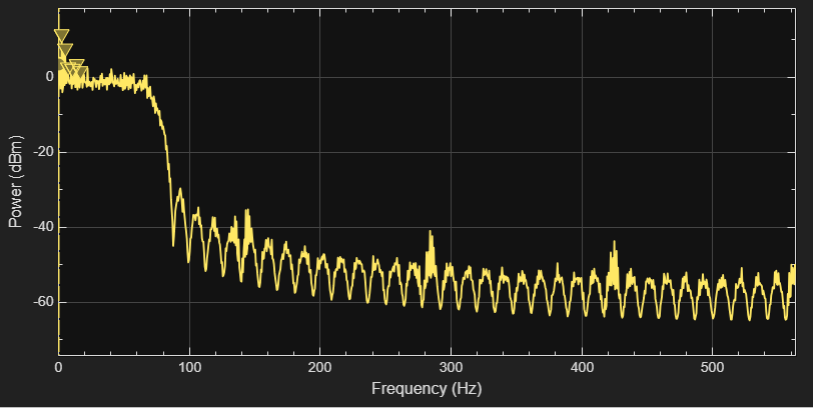

*symbol rate = 500*

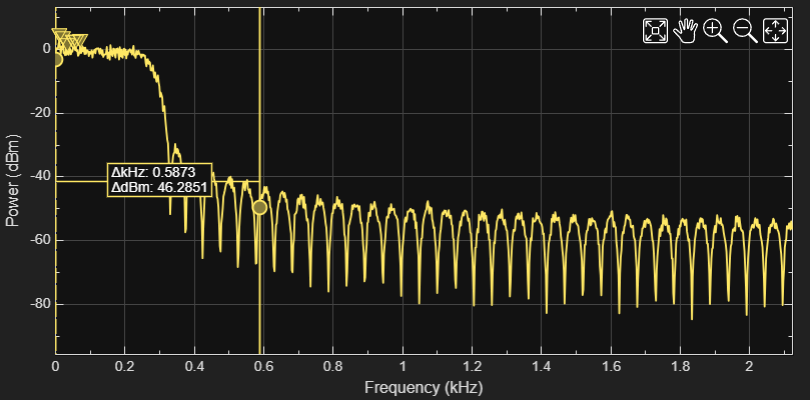

*symbol rate = 1000*

*symbol rate = 2000*

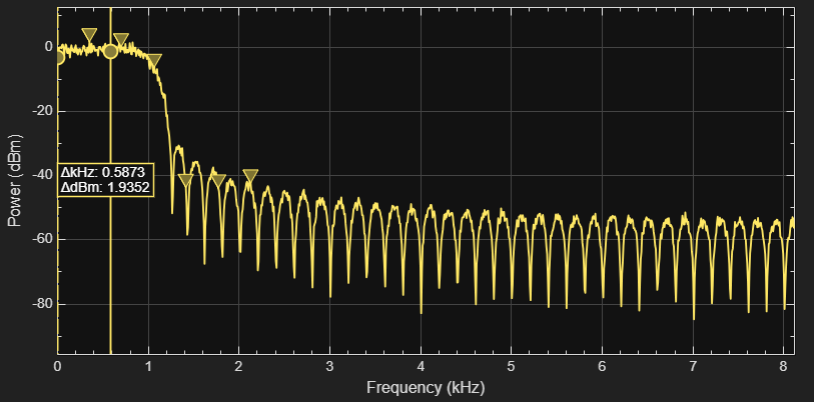

*symbol rate = 5000*

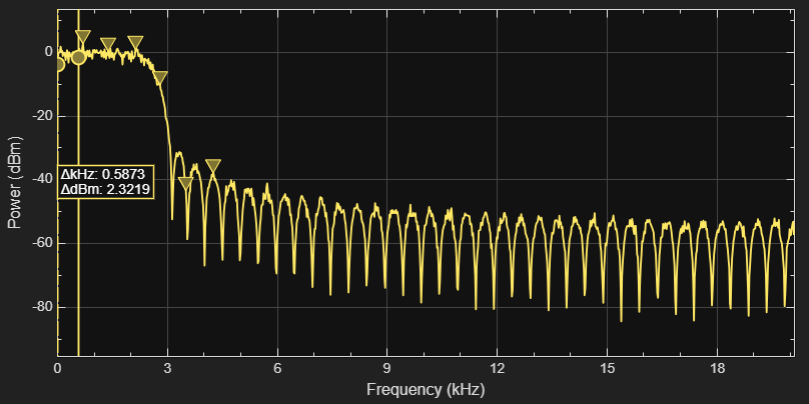

Change the pulse shaping filter roll-off-factor *alpha *setting in the live script and observe how the baseband bandwidth of the signal changes.

Explain your observations and compare it to the theoretical predictions. 

*Observations:*

- *higher symbol rate -> bigger bandwidth*

- *higher roll-off-factor -> bigger bandwidth, smaller side lobes*

*This makes sense, considering the theoretical framework:*

- *In our model, increacing the symbol rate modifies the rate at which the Bernoilli sequence generates values. Consider the BPSK scheme. There, the square funtion of 1 and -1 changes faster. Each rectangle pulse is shorter, so in the frequency domain, the function is wider (greater bandwidth). When passing through the raised cosine filter, the resulting signal mantains a wider bandwidth than the original one. In a the QPSK scheme, the same ocurrs: a faster bitstream compresses our time-domain signal, which in turn dilates its frequency spectrum, increacing bandwidth.*

- *The roll-off-factor in a raised cosine filter increaces decay of the wave in the frequency domain, thus reducing bandwidth. The trade-off, is that it might increace amplitude in the time domain, which might result in more bit errors. If you look at the formula of a raised cosine:*

How is the number of processed bits affected by the symbol rate and modulation scheme?

*Both the symbol rate and modulation scheme have a direct effect on the bit rate. Depending on the modulation scheme chosen, the symbol can represent a different number of bits. For example, each BPSK symbol represents 1 bit, wheras each QPSK represents 2 bits. Therefore, the bit rate equals the product between the symbol rate and the number of bits contained in one symbol. Consequently, the number of processed bits within a time interval is affected.*

`Task 4: SNR vs BER`

Observe how the Bit-Error-Rate (BER) of the passband communication system changes with different configurations of the *Signal-to-Noise *ratio setting of the *Channel *block. Collect statistics for various configurations and plot SNR against BER. For BPSK and QPSK, confirm your findings with corresponding theoretical predictions (Keywords: BER, probability of error).

**Note: Statistics of SNR vs BER data are collected during the simulation and recoreded into 'out.SNRvBER'. You will need to do a little bit of data shuffling and re-organisation to do this. Tip: Inspect SNRvBER **

simTime_ = 1;

n = 21;

SNR_values = linspace(0, 10, n);
BER_values = zeros(1, n);

for i = 1:1:n
    SNR = Simulink.Parameter(SNR_values(i))
    out_i = sim("CommSysSimulink.slx",'StopTime',string(simTime_),'SimulationMode', 'normal');
    BER_values(i) = out_i.SNRvBER(1,2,1);     % take first result from simulated value.
end



figure; plot(SNR_values, BER_values, '-o')
xlabel("SNR")
ylabel("BER")
grid on
title("SNR vs. BER")